% Clear Workspace
clear all
clc

% Read STL File
stl1 = stlread("Test Objects\Cylinder.STL");

% Create UniformSliceGeneratorObject
uSGO1 = FlatUniformSliceGenerator(stl1, 2)

uSGO1 =   FlatUniformSliceGenerator with properties:

                 obj: []
    connectivityList: [236×3 double]
       numOfElements: 236
              points: [120×3 int64]
      sliceThickness: 2
           slicePath: [0×3 double]


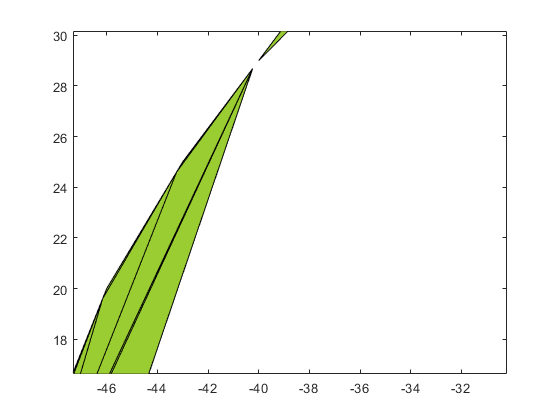


test = uSGO1.slice(8)


% Generate
figure(3)
uSGO1.generateSlices()
op = uSGO1.getSlicePath()

% Show
figure(4)
plot3(op(:,1), op(:,2), op(:,3),'-r*','LineWidth',2);
xlabel('x')
ylabel('y')
view(3);
hold on